x = out.logsout.get("x").Values.Data;
y = out.logsout.get("y").Values.Data;
z = out.logsout.get("h").Values.Data;

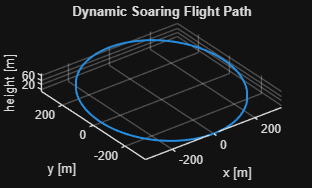

figure
plot3(x,y,z,'LineWidth',1.5)
grid on
xlabel('x [m]')
ylabel('y [m]')
zlabel('height [m]')
title('Dynamic Soaring Flight Path')
axis equal

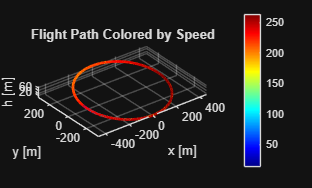

v = out.logsout.get("v").Values.Data;   % speed

figure

surface( ...
    [x x], ...
    [y y], ...
    [z z], ...
    [v v], ...
    'FaceColor','none', ...
    'EdgeColor','interp', ...
    'LineWidth',2);

colormap(jet)
colorbar

xlabel('x [m]')
ylabel('y [m]')
zlabel('h [m]')

title('Flight Path Colored by Speed')

grid on
axis equal
view(3)

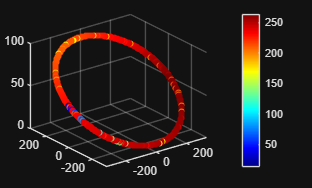

scatter3(x,y,z,20,v,'filled')
colormap(jet)
colorbar